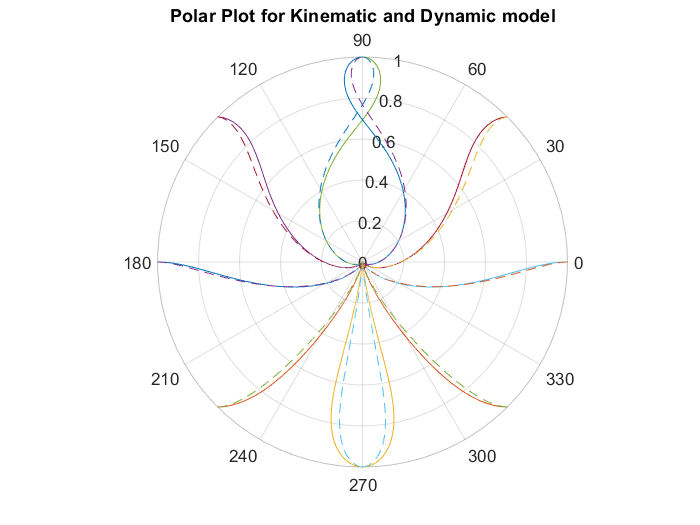

% Name : Vipul Jain          Roll.No : 180869

tspan = [0 :0.001: 20];
arr = [0;pi/4;pi/2;-pi/4;-pi/2];

% Dashed lines are for Dynmic Model.
for i = 1:5
    iniCon = [1;arr(i);pi/2];
    [t, x] = ode45(@(t,x) Kinematic(t,x), tspan, iniCon);
    polarplot((pi)+((pi/2)-(x(:,3))+(x(:,2))),x(:,1))
    hold on
end
for i = 1:5
    iniCon = [1;arr(i);-pi/2];
    [t, x] = ode45(@(t,x) Kinematic(t,x), tspan, iniCon);
    polarplot((pi)+((pi/2)-(x(:,3))+(x(:,2))),x(:,1))
    hold on
end

for i = 1:5
    iniCon = [0;0;1;arr(i);pi/2];
    [t, x] = ode45(@(t,x) Dynamic(t,x), tspan, iniCon);
    polarplot(pi+((pi/2)-(x(:,5))+(x(:,4))),x(:,3),'--')
    hold on
end
for i = 1:5
    iniCon = [0;0;1;arr(i);-pi/2];
    [t, x] = ode45(@(t,x) Dynamic(t,x), tspan, iniCon);
    polarplot(pi+((pi/2)-(x(:,5))+(x(:,4))),x(:,3),'--')
    hold on
end
hold off

title('Polar Plot for Kinematic and Dynamic model')

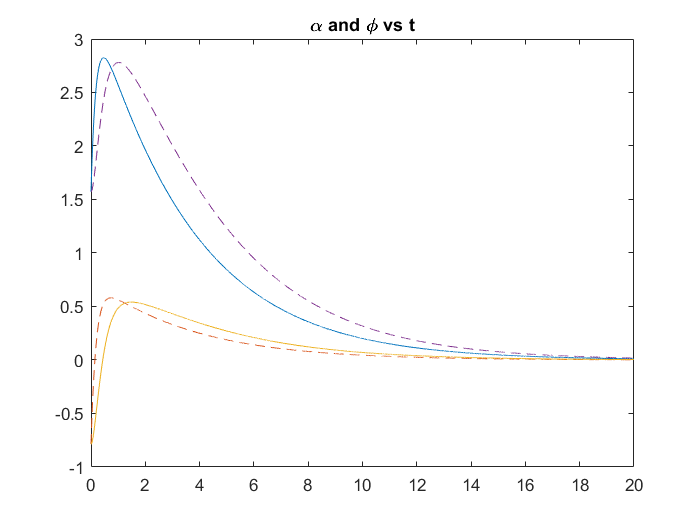


iniCon = [1;-pi/4;pi/2];
[t, x] = ode45(@(t,x) Kinematic(t,x), tspan, iniCon);
plot(t,x(:,3),t,x(:,2),'--')

hold on

iniCon = [0;0;1;-pi/4;pi/2];
[t, x] = ode45(@(t,x) Dynamic(t,x), tspan, iniCon);
plot(t,x(:,4),t,x(:,5),'--')

hold off

title('\alpha and \phi vs t')

function dxdt = Kinematic(t, x)   %Kinematic Model 
    Ka = 8;
    Kp = 1;
    Kf = -1.5;
    dxdt = zeros(3,1);
    dxdt(1) = -Kp*cos(x(2))*x(1);
    dxdt(2) = -Ka*x(2) -Kf*x(3) + Kp*sin(x(2));
    dxdt(3) = -Ka*x(2) - Kf*x(3);
end

function dxdt = Dynamic(t, x)   %Dynamic Model 
    Ka = 8;
    Lambda1 = 1.2;
    Lambda2 = 3.5;
    Kp = 1;
    Kf = -1.5;
    dxdt = zeros(5,1);
    dxdt(1) = -Kp*x(1)*cos(x(4)) - Lambda1*(x(1)-Kp*x(3));
    dxdt(2) = Ka*((x(1)*sin(x(4))/x(3))-x(2)) - Kf*x(2) - Lambda2*(x(2)-Ka*x(4)-Kf*x(5));
    dxdt(3) = -x(1)*cos(x(4));
    dxdt(4) = (x(1)*sin(x(4))/x(3))-x(2);
    dxdt(5) = -x(2);
end